# FDFD 2D solver for eigenmode: Metallic Transmission Line

**Metallic transmission lines**, often employed in plasmonics and microwave engineering, support modes with strong field confinement and unique dispersion properties due to their interaction with the metal-dielectric boundary.

The eigenmode solver computes the guided modes supported by the transmission line, including their field profiles and effective indices, providing valuable insights into the wave propagation characteristics of the structure.

### Step 0: Global Settings

The simulation begins by initializing the `Model2D` instance and configuring the global settings. The working plane is set to the $y-z$** plane**, which defines the 2D cross-sectional area for analysis. The operating frequency is set to **1 GHz**, corresponding to a wavelength of approximately **0.2998 m**. These parameters establish the foundational setup for the simulation.

% physics constant
eps0 = Constant('eps0').v;
c0 = Constant('c0').v;

modelTL = Model2D.initialize();

Model2D: Object Reset and Initialized


modelTL.setLabel('yz'); % work on z-x plane
f = 1e9; % frequency, unit: Hz
wavelength = c0/f;
modelTL.setWavelength(wavelength); % work at 0.2998 m wavelength

### Step 1: Device parameters 

#### 1.1 Geometry parameters

The geometry of the metallic transmission line is defined by the dimensions of its simulation domain, conductive layers, and substrate. These parameters ensure an accurate representation of the transmission line's structure within the simulation.

% size parameters [unit: um]
W = 3000;
H = 800;
d_cond_down = 100;
d_substrate = 500;
d_cond_up = 35;
w_cond_up = 1000;

#### 1.2 Metal material information

Because the conductor is made of metals, its complex relative permittivity is depended on frequency of transfered wave, $\tilde{\varepsilon_r}=1+\frac{\sigma}{i\omega\varepsilon_0}$. The substrate material FR-4 also has lossy property, so that its complex relative permittivity can be defined as $\tilde{\varepsilon_r}=\varepsilon_r(1-i\tan\delta)$.

% air background box
eps_air = 1;

% cooper conductor
sigma = 5.8e7; % conductivity
eps_cond = 1 + sigma/(1i*2*pi*f*eps0);

% FR-4 substrate
eps0_sub = 4.4; 
tand  = 0.03;
eps_sub = eps0_sub*(1 - 1i*tand);

### Step 2: Build up simulation device

This step constructs the simulation domain by defining the geometry and assigning material properties to the air background, conductors, and substrate. Each component is added to the model as a separate device.

#### 2.1 Air background box

The simulation domain is encapsulated by an air background box, providing a neutral medium around the transmission line.

modelTL.addDevice(1);
modelTL.setDevice(1).setGeometry('Rectangle', W, H, 'bl', [-W/2, 0], 'um');
modelTL.setDevice(1).setMaterial(eps_air);

#### 2.2 Cooper conductor

The conductors are modeled as two rectangles:

- The lower conductor is placed at the base of the simulation domain.

- The upper conductor is positioned above the substrate at the specified offset.

% lower conductor
modelTL.addDevice(2);
modelTL.setDevice(2).setGeometry('Rectangle', W, d_cond_down, 'bl', [-W/2, 0], 'um');
modelTL.setDevice(2).setMaterial(eps_cond);

% upper conductor
modelTL.addDevice(3);
modelTL.setDevice(3).setGeometry('Rectangle', w_cond_up, d_cond_up, 'bl', [-w_cond_up/2, d_cond_down+d_substrate], 'um');
modelTL.setDevice(3).setMaterial(eps_cond);

#### 2.3 FR-4 substrate

The substrate is positioned between the upper and lower conductors, filling the gap with its lossy material properties.

modelTL.addDevice(4);
modelTL.setDevice(4).setGeometry('Rectangle', W, d_substrate, 'bl', [-W/2, d_cond_down], 'um');
modelTL.setDevice(4).setMaterial(eps_sub);

#### 2.4 Build up real device

Once all components are added, the `finishDevice` method finalizes the setup, and `dispImg` provides a visual representation of the constructed geometry.

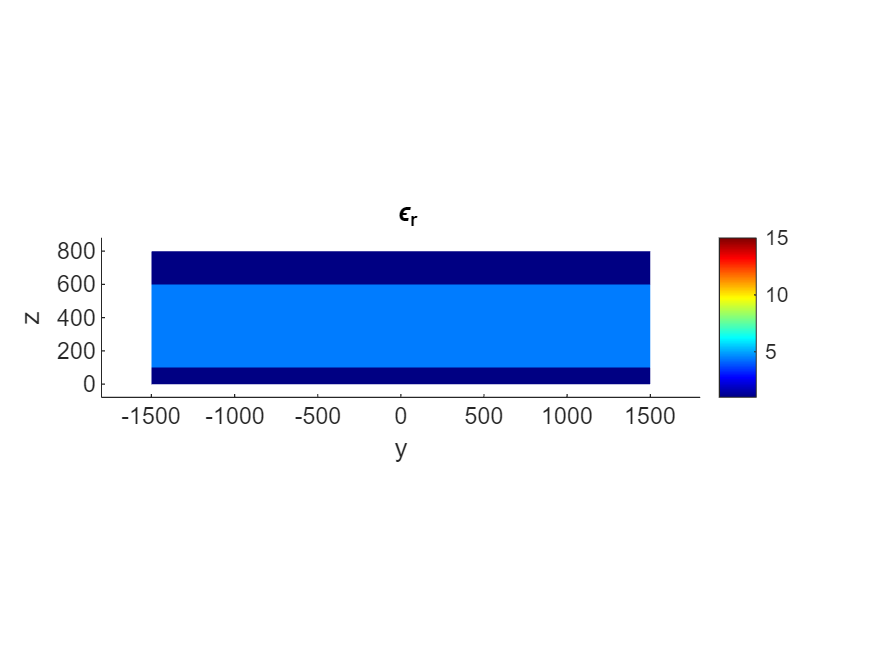

modelTL.assembleDevice;
modelTL.device.dispImg;

### Step 3: FDFD region mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

% grid size
Ny = 151; 
Nz = 201;

dy = 20; % unit: um
dz = 5;

% set mesh grid
modelTL.setMesh([Ny, Nz], [dy, dz], "Unit", 'um', "Center", [0, 400]);

### Step 4: Choose FDFD solver

The simulation requires a solver to calculate the electromagnetic fields and eigenmodes of the metallic transmission line. In this step, the `EigenMode `solver is selected, which is specifically designed to compute the guided modes supported by the structure. This solver analyzes the field distribution and effective indices of the eigenmodes.

modelTL.setSolver('EigenMode');

### Step 5: Solve eigenmode

In this step, the simulation computes the **fundamental eigenmode** of the metallic transmission line. The fundamental mode represents the primary guided mode supported by the structure, with its field distribution determined by solving the eigenmode equation.

num_mode = 1; % fundamental mode
modelTL.solve(num_mode);

The computed eigenmode is visualized, showing the intensity of the electric field component $|E_y|$ across the simulation domain. This helps verify the mode shape and confinement properties.

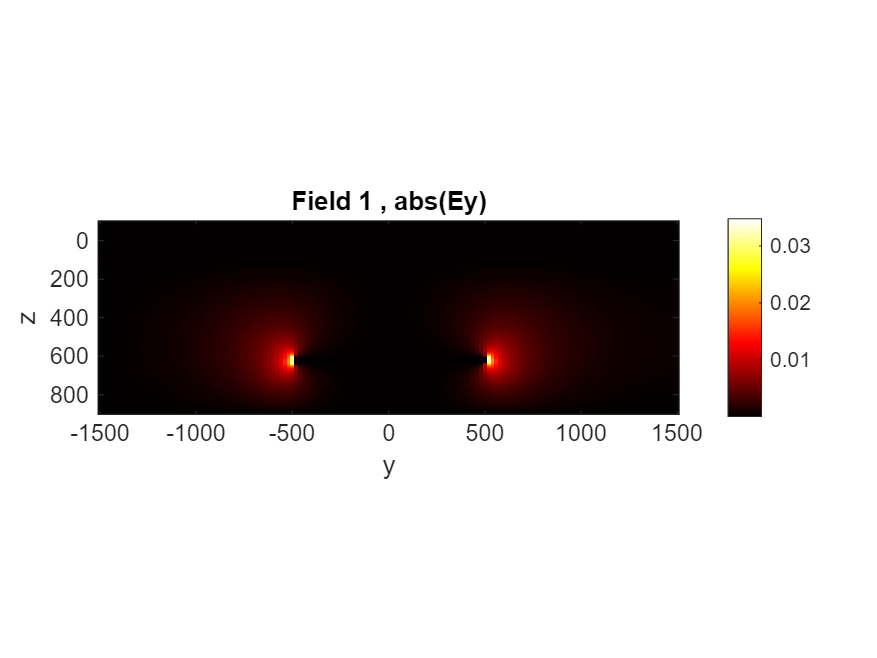

modelTL.dispField('Ey');

solution = modelTL.exportResult;

The simulated field distribution of the **fundamental eigenmode** appears as expected, with strong confinement around the conductive regions of the transmission line. The symmetric field profile and smooth intensity gradients confirm the efficient guiding of electromagnetic waves in the metallic structure. The results align well with theoretical predictions, demonstrating the accuracy and reliability of the FDFD EigenMode solver for analyzing metallic transmission lines.